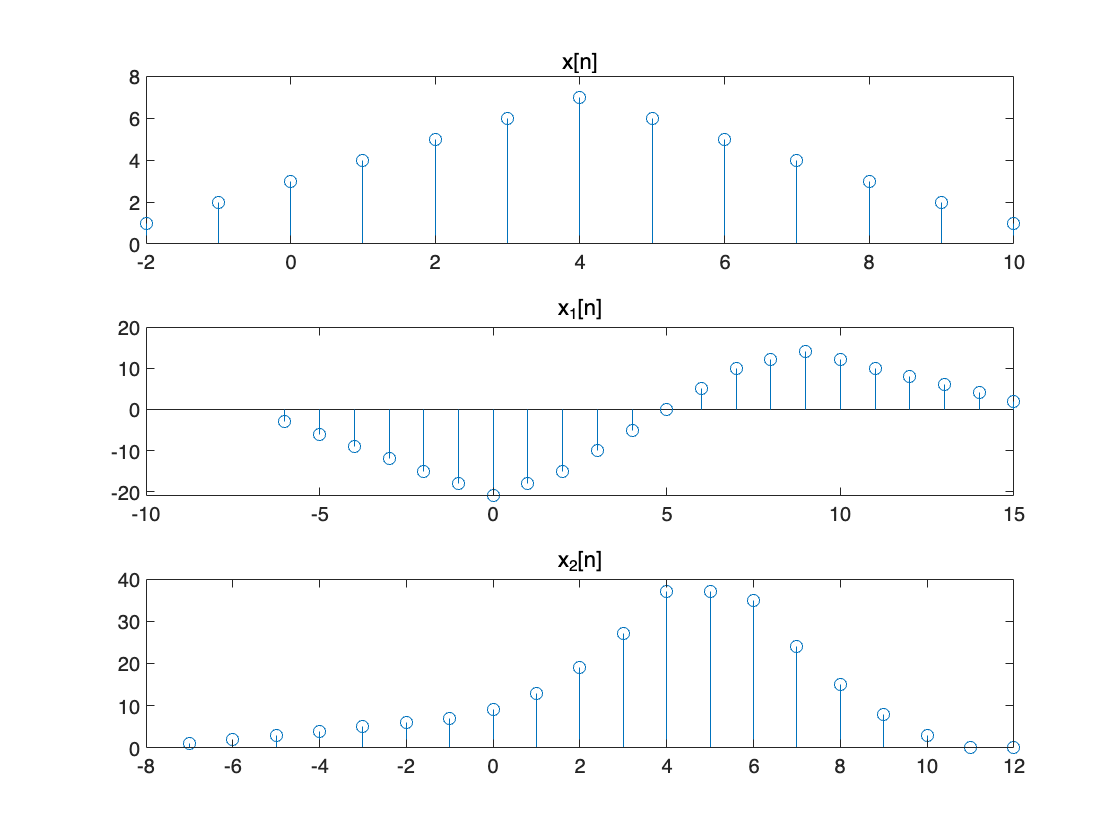

clc;
clf;
clear;
close;
n1=4:10; x1=7:-1:1;
n2=-2:3; x2=1:6;
[x,n]=sigadd(x1,n1,x2,n2);
[y1,n3]=sigshift(x,n,5);
[y2,n4]=sigshift(x,n,-4);
[x_1,n5]=sigadd(2*y1,n3,-3*y2,n4);
[y3,n6]=sigshift(x,n,-3);
[y4,n7]=sigfold(y3,n6);
[y5,n8]=sigshift(x,n,2);
[y6,n9]=sigmult(x,n,y5,n8);
[x_2,n10]=sigadd(y4,n7,y6,n9);
figure(2)
subplot(3,1,1); stem(n,x); title("x[n]");
subplot(3,1,2); stem(n5,x_1); title("x_1[n]");
subplot(3,1,3); stem(n10,x_2); title("x_2[n]");